# Release Upgrade Workflow

The first step of the upgrade process is to run requirements-based tests in the new version and compare the results with the old version.

% Test file containing requirements-based tests
testFileName = 'CruiseControl_TestSuite.mldatx';

When using multi-release testing in Simulink Test for the first time, register the old release in the Test Manager by pointing to the MATLAB instal location. This can be done directly from the test case or by opening the Test Manager and going to **Preferences > Release > Add/Remove releases**.

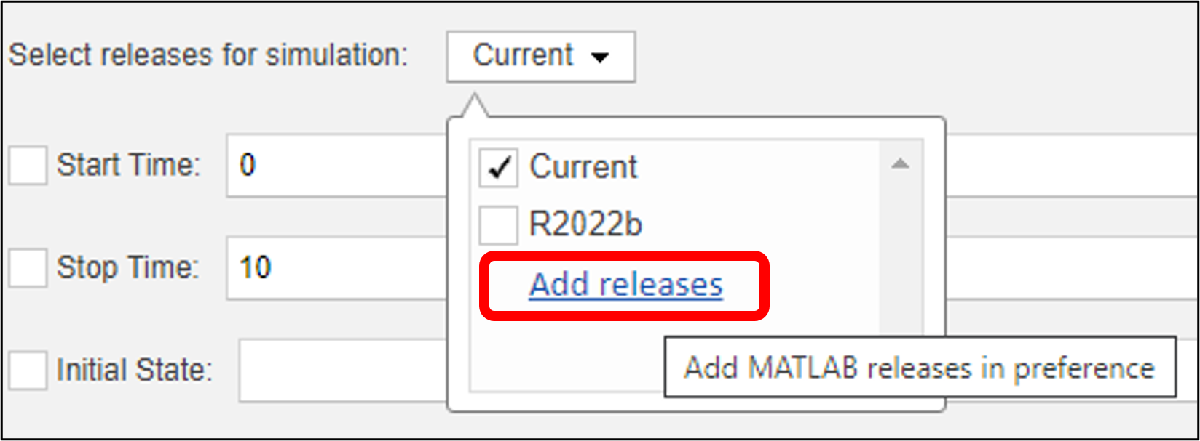

% Open the Test Manager
sltestmgr
% Release this project is being upgraded from
OldRelease = 'R2022b';
% Load the test file
sltest.testmanager.load('CruiseControl_TestSuite.mldatx');

Upgrading the original models to the latest release would modify them and change the release they were saved in, preventing them from being run in the old release. To avoid modifying the original files, make a copy of the models and run the Upgrade Advisor checks on the copies.

% Create a new folder in the current directory and copy the models and
% harnesses to it
newDir = 'Upgraded Models';
mkdir(newDir);

% Get a list of all models in the project
modelList = dir('Models\*.slx');
for mdl = modelList
    [~, mdlName, ~] = fileparts(mdl.name);
    load_system(mdlName);
    mkdir([newDir '/' mdlName]);
    save_system(mdlName, [newDir '/' mdlName '/' mdlName '_upgraded.slx']);
end

% Add new directory to the project
newFolder = addFolderIncludingChildFiles(currentProject, newDir);
addpath(genpath(newDir));

 Open the Upgrade Advisor for the project. To do so, on the **Project** tab, click the down arrow to expand the **Tools** gallery. Under **Project Checks**, click **Upgrade Project.**

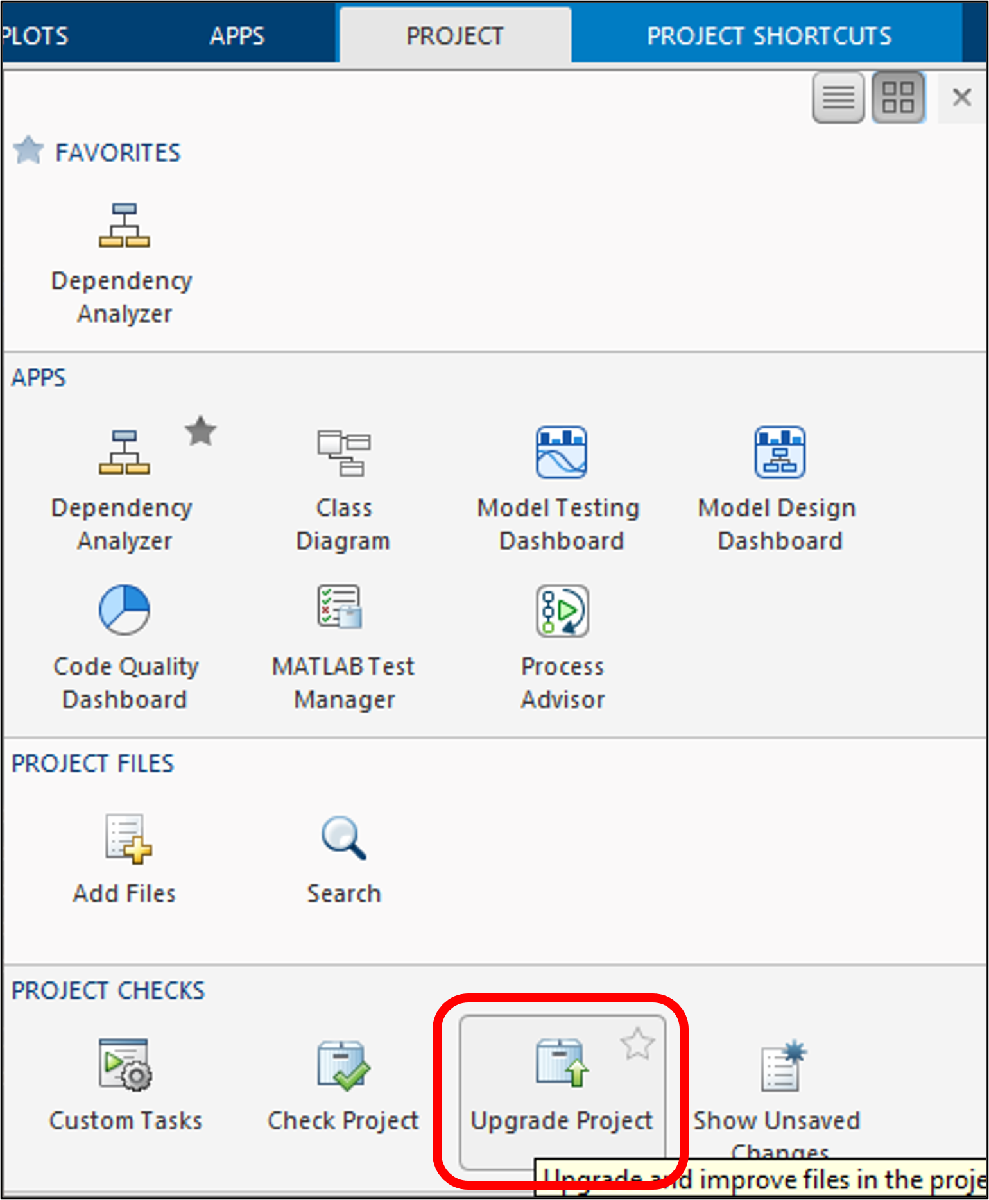

Select only the newly created directory for analysis and run click on **Upgrade**.

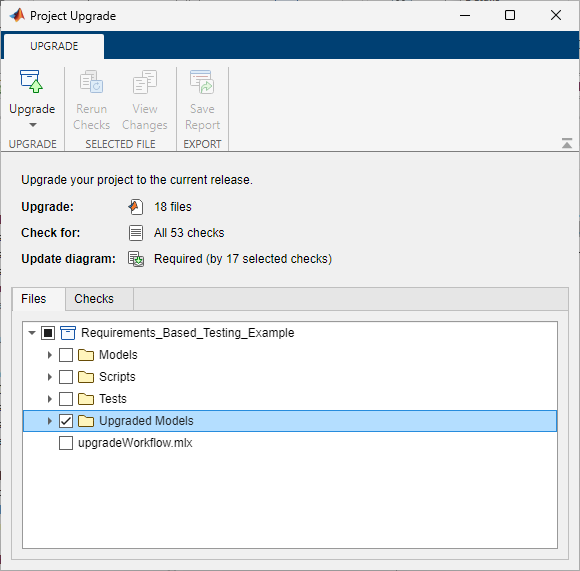

Make sure to not include any other files in the upgrade process.

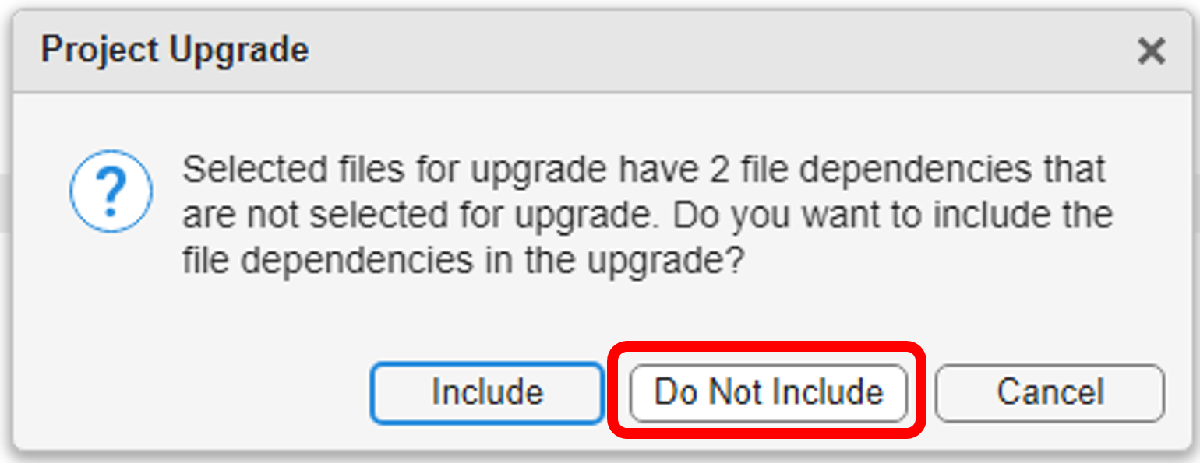

To compare results in two releases, first make a copy of the requirements-based tests. Then, convert each test case to a equivalence test, setting the old release as the baseline of comparison. The function `createUpgradeTestSuite `handles both steps, as well as capturing the equivalence criteria.

testFile = createUpgradeTestSuite(testFileName, OldRelease);

The upgrade equivalence tests are grouped in new test suites.

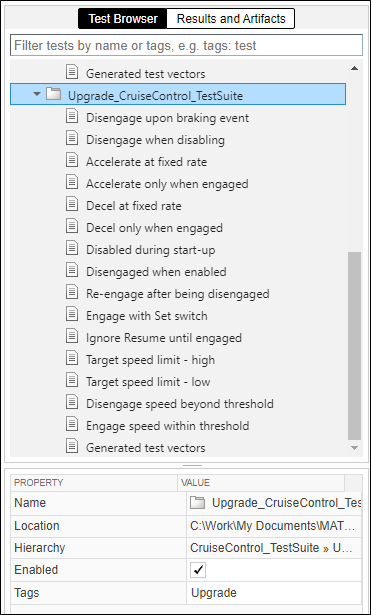

The next step is to run the upgrade test suites, which can be identified via a tagged added to them by `createUpgradeTestSuite`. Each passing test not only confirms that the system under test passes the requirements-based tests in the new release, but it also confirms numerical equivalence between the two releases for all outputs and logged signals in the test harness.

for ts = testFile.getTestSuites()
    % Only run upgrade equivalence tests
    if any([~strcmp(ts.Tags, 'Upgrade') isempty(ts.Tags)])
        continue
    end
    
    res = run(ts);

After running the each test suite, confirm that the tests achieve full structural coverage in both releases. This is a crucial step, because unexercised portions of the model could contain functional changes that affect the models in the new release. To do so, extract the aggregated coverage results and check that the decision and condition coverage objectives equal 100%. If there is any missing coverage, create a new test case

    modelInfos = [res.getCoverageResults.modelinfo];
    modelNames = {modelInfos.analyzedModel};
    mergeRes = res;
    for mdl = 1:length(modelNames)
        covRes = mergeRes.getCoverageResults(modelNames{mdl});
        decRes = decisioninfo(covRes, covRes.modelinfo.analyzedModel);
        conRes = conditioninfo(covRes, covRes.modelinfo.analyzedModel);

        if decRes(1)/decRes(2) ~= 1 || conRes(1)/conRes(2) ~= 1
            disp(['Missing Coverage for Model ' covRes.modelinfo.analyzedModel]);
            disp(['Generating tests to exercise missing coverage objectives' newline]);

            % Generate tests to achieve full coverage
            newTests = generateTestsForMissingCoverage(ts, covRes, OldRelease);

            % Run generated tests to make sure they pass and to collect
            % more coverage data
            newRes = run(newTests);
            newCov = newRes.CoverageResults;

            % Merge new coverage results with old coverage results
            mergeRes = sltest.testmanager.mergeCoverage([mergeRes, newRes]);
        end
    end
end

After resolving any test failures and generating new tests for any missing coverage, the next step is to rerun the upgrade equivalence tests in SIL to confirm that code generation also behaves as expected, and that the code coverage also reaches 100%.

for ts = testFile.getTestSuites()
    % Only run upgrade equivalence tests
    if any([~strcmp(ts.Tags, 'Upgrade') isempty(ts.Tags)])
        continue
    end
    % This time run in SIL
    res = run(ts, 'SimulationMode', 'Software-in-the-Loop');

    modelInfos = [res.getCoverageResults.modelinfo];
    modelNames = {modelInfos.analyzedModel};
    mergeRes = res;
    for mdl = 1:length(modelNames)
        covRes = mergeRes.getCoverageResults(modelNames{mdl});

        % Test generation not supported for SIL results from old release
        testVersion = covRes.dbVersion(2:end-1);
        if strcmp(OldRelease, testVersion)
            continue
        end

        decRes = decisioninfo(covRes, covRes.modelinfo.analyzedModel);
        conRes = conditioninfo(covRes, covRes.modelinfo.analyzedModel);

        if decRes(1)/decRes(2) ~= 1 || conRes(1)/conRes(2) ~= 1
            disp(['Missing Coverage for Model ' covRes.modelinfo.analyzedModel ' in SIL']);
            disp(['Generating tests to exercise missing coverage objectives' newline]);

            % Generate tests to achieve full coverage
            newTests = generateTestsForMissingCoverage(ts, covRes, OldRelease);

            % Run generated tests to make sure they pass and to collect
            % more coverage data
            newRes = run(newTests);
            newCov = newRes.CoverageResults;

            % Merge new coverage results with old coverage results
            mergeRes = sltest.testmanager.mergeCoverage([mergeRes, newRes]);
        end
    end
end

After test generation is complete, inspect the results to see if there is any missing coverage remaining. The MIL tests achieve full coverage, but there is still one uncovered decision objective for the SIL tests.

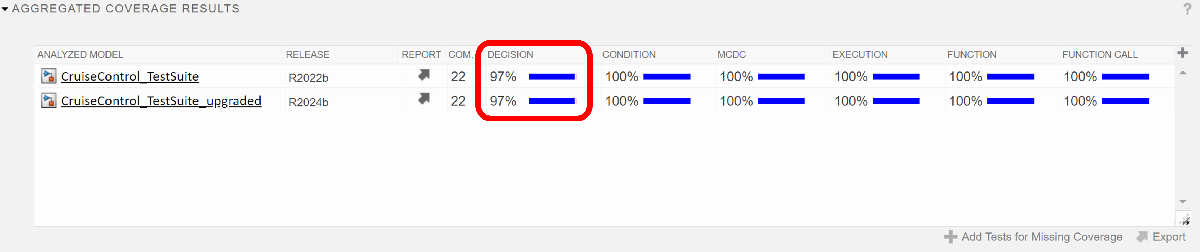

Click on the name of the upgraded model to open the coverage report and display it on the model.

open_system(covRes.modelinfo.analyzedModel);
cvmodelview(covRes);

Upon closer inspection see that the one uncovered objective is a block of code that prevents integer overflow on a temporal counter.

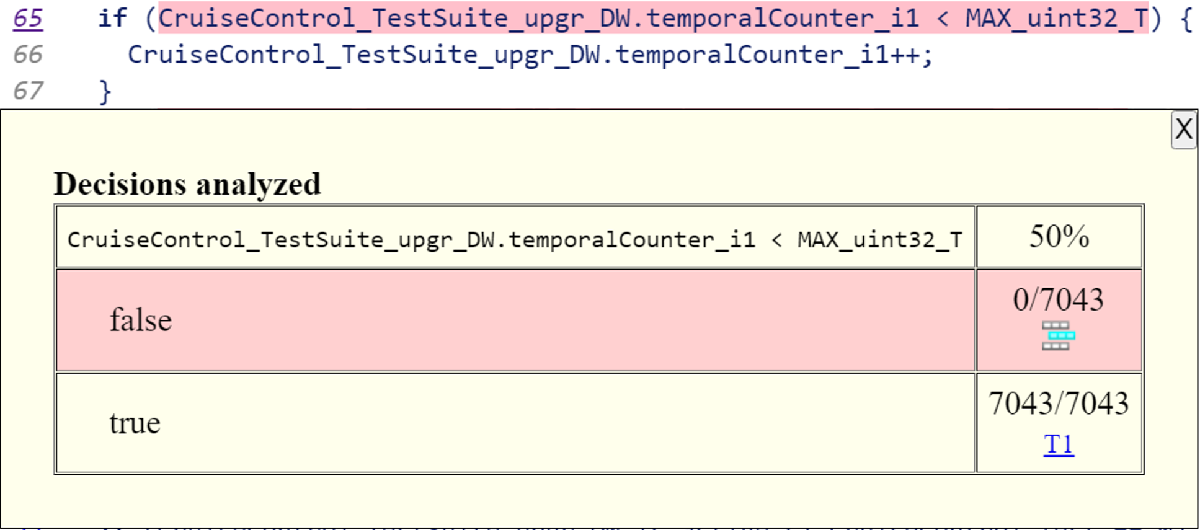

To cover this objective, a test would have to have 2^32 timesteps. On these grounds, it is reasonable to justify the missing coverage and apply a filter to the coverage results. See this [example](https://www.mathworks.com/help/slcoverage/ug/creating-and-using-coverage-filters.html) in the Simulink Coverage documentation for more details on how to create a filter.

Now that all the tests pass and that all structural coverage objectives are either fully covered or properly justified, the project upgrade verification is complete.

Close all open models.

bdclose('all');

Remove upgraded files from project.

removeFile(currentProject, newFolder);
rmpath(genpath(newDir));

*Copyright 2024 The MathWorks, Inc.*